Periodic


$$fundamental\_period = 2$$

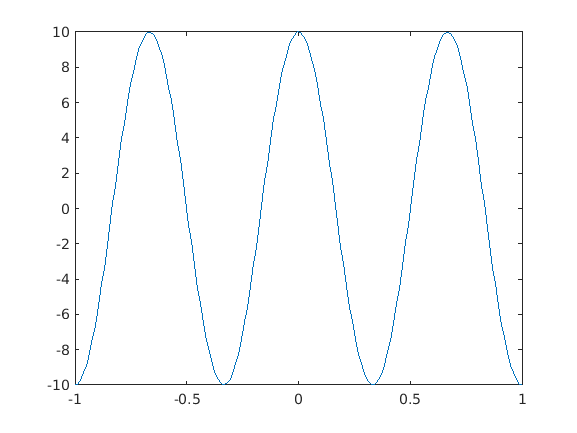

clc;
clear;
close all;

A = 10;
n = -1:0.01:1;
w = input('Enter the value of w');
wave = A.*cos(w*n);
x = (2*pi) / w;
[fundamental_period, j] = numden(sym(x));
for k=-100:1:100
    if fundamental_period==k*pi
        disp('Aperiodic');
        break;
    elseif fundamental_period == k
        disp('Periodic');
        display(fundamental_period);
        
        figure(1);
        subplot(1,1,1);
        plot(n, wave);
        break;
    end
end